# Multirotor Simulator

This tutorial shows how to define and simulate a multirotor robot and how to design a controller to control the attitude and the position of this robot.

In order to be able to run the simulator, first we should add its files to the path:

addpath('simulator');

Feel free to explore this directory to get familiar. The main scripts we will be playing with are `multirotor, simulation and controller.`

## Multirotor Definition

Let's define a new multirotor. We can define the multirotor by defining the arrangement of its arms (the angles of the arms locations with respect to the forward direction). The number of angles also defines how many rotors we will have in the multirotor. For example, if you want a quadrotor, you should choose 4 angles, but a hexarotor would need 6 angles.

Note that we assume NED frame, therefore the angles will be clockwise if you're loocking at the multirotor from the top. Feel free to change the default values:

RotorPlacementAngles = [45, 135, 225, 315];

Let's also define the directions of the rotor rotations (-1 is for clockwise and 1 is for counter-clockwise around Z. It's the same if you are looking from the top):

RotorRotationDirections = [-1, 1, -1, 1];

Good! Now let's construct our multirotor object from our definitions:

m = multirotor(RotorPlacementAngles, RotorRotationDirections)

m =   multirotor with properties:

           Rotors: {4×1 cell}
             Mass: 3
          Gravity: [3×1 double]
                I: [3×3 double]
    PayloadRadius: 0.1500
      NumOfRotors: 4
     InitialState: [1×1 struct]
            State: [1×1 struct]


Feel free to explore the structure of the multirotor object. You will see that it has an array of Rotors that describes the specifications of the rotors. You can change the properties of the multirotor and each individual rotor. However, you would need to call `m.UpdateStructure()` function to recalculate the inertia tensor if you change the structure (e.g., angles, masses, lengths, etc.).

## Visualization

Now is time to see how your multirotor looks like:

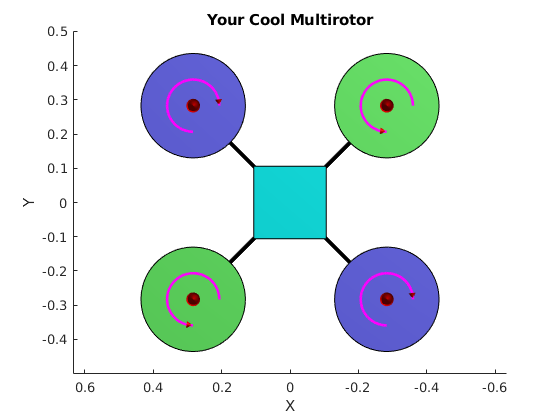

m.Visualize()

Remember that the front is the positive `X` direction.

Feel free to open the figure in a separate window (click on the button at the top-right of the figure when you move the mouse on it). You will be able to explore the structure in 3-D by choosing `Rotate 3D` from the `Tools` menu.

## Simulation